# Build and train neural network

Create new deep networks for classification, regression, and forecasting tasks by defining the network architecture and training the network from scratch.

After defining the network architecture, you can define training parameters using the [`trainingOptions`](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function. You can then train the network using the [`trainnet`](https://www.mathworks.com/help/deeplearning/ref/trainnet.html) function. Use the trained network to predict class labels or numeric responses, or forecast future time steps. If the [`trainingOptions`](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function does not provide the training options that you need for your task, or custom output layers do not support the loss functions that you need, then you can define a custom training loop.

## Build a neural network and visualize the layers

If you have a data set of numeric features (for example a collection of numeric data without spatial or time dimensions), then you can train a deep learning network using a feature input layer. It is programmatically created in this function. 

net = buildFCNetwork(); 

You can also interactively design and edit the network using the [Deep Network Designer app](https://www.mathworks.com/help/deeplearning/deep-network-designer-app.html). 

deepNetworkDesigner(net); 

The network is not yet trained but analysis can be performed to understand the achitecture and potential for compression using the Analyze for Compression functionality. 

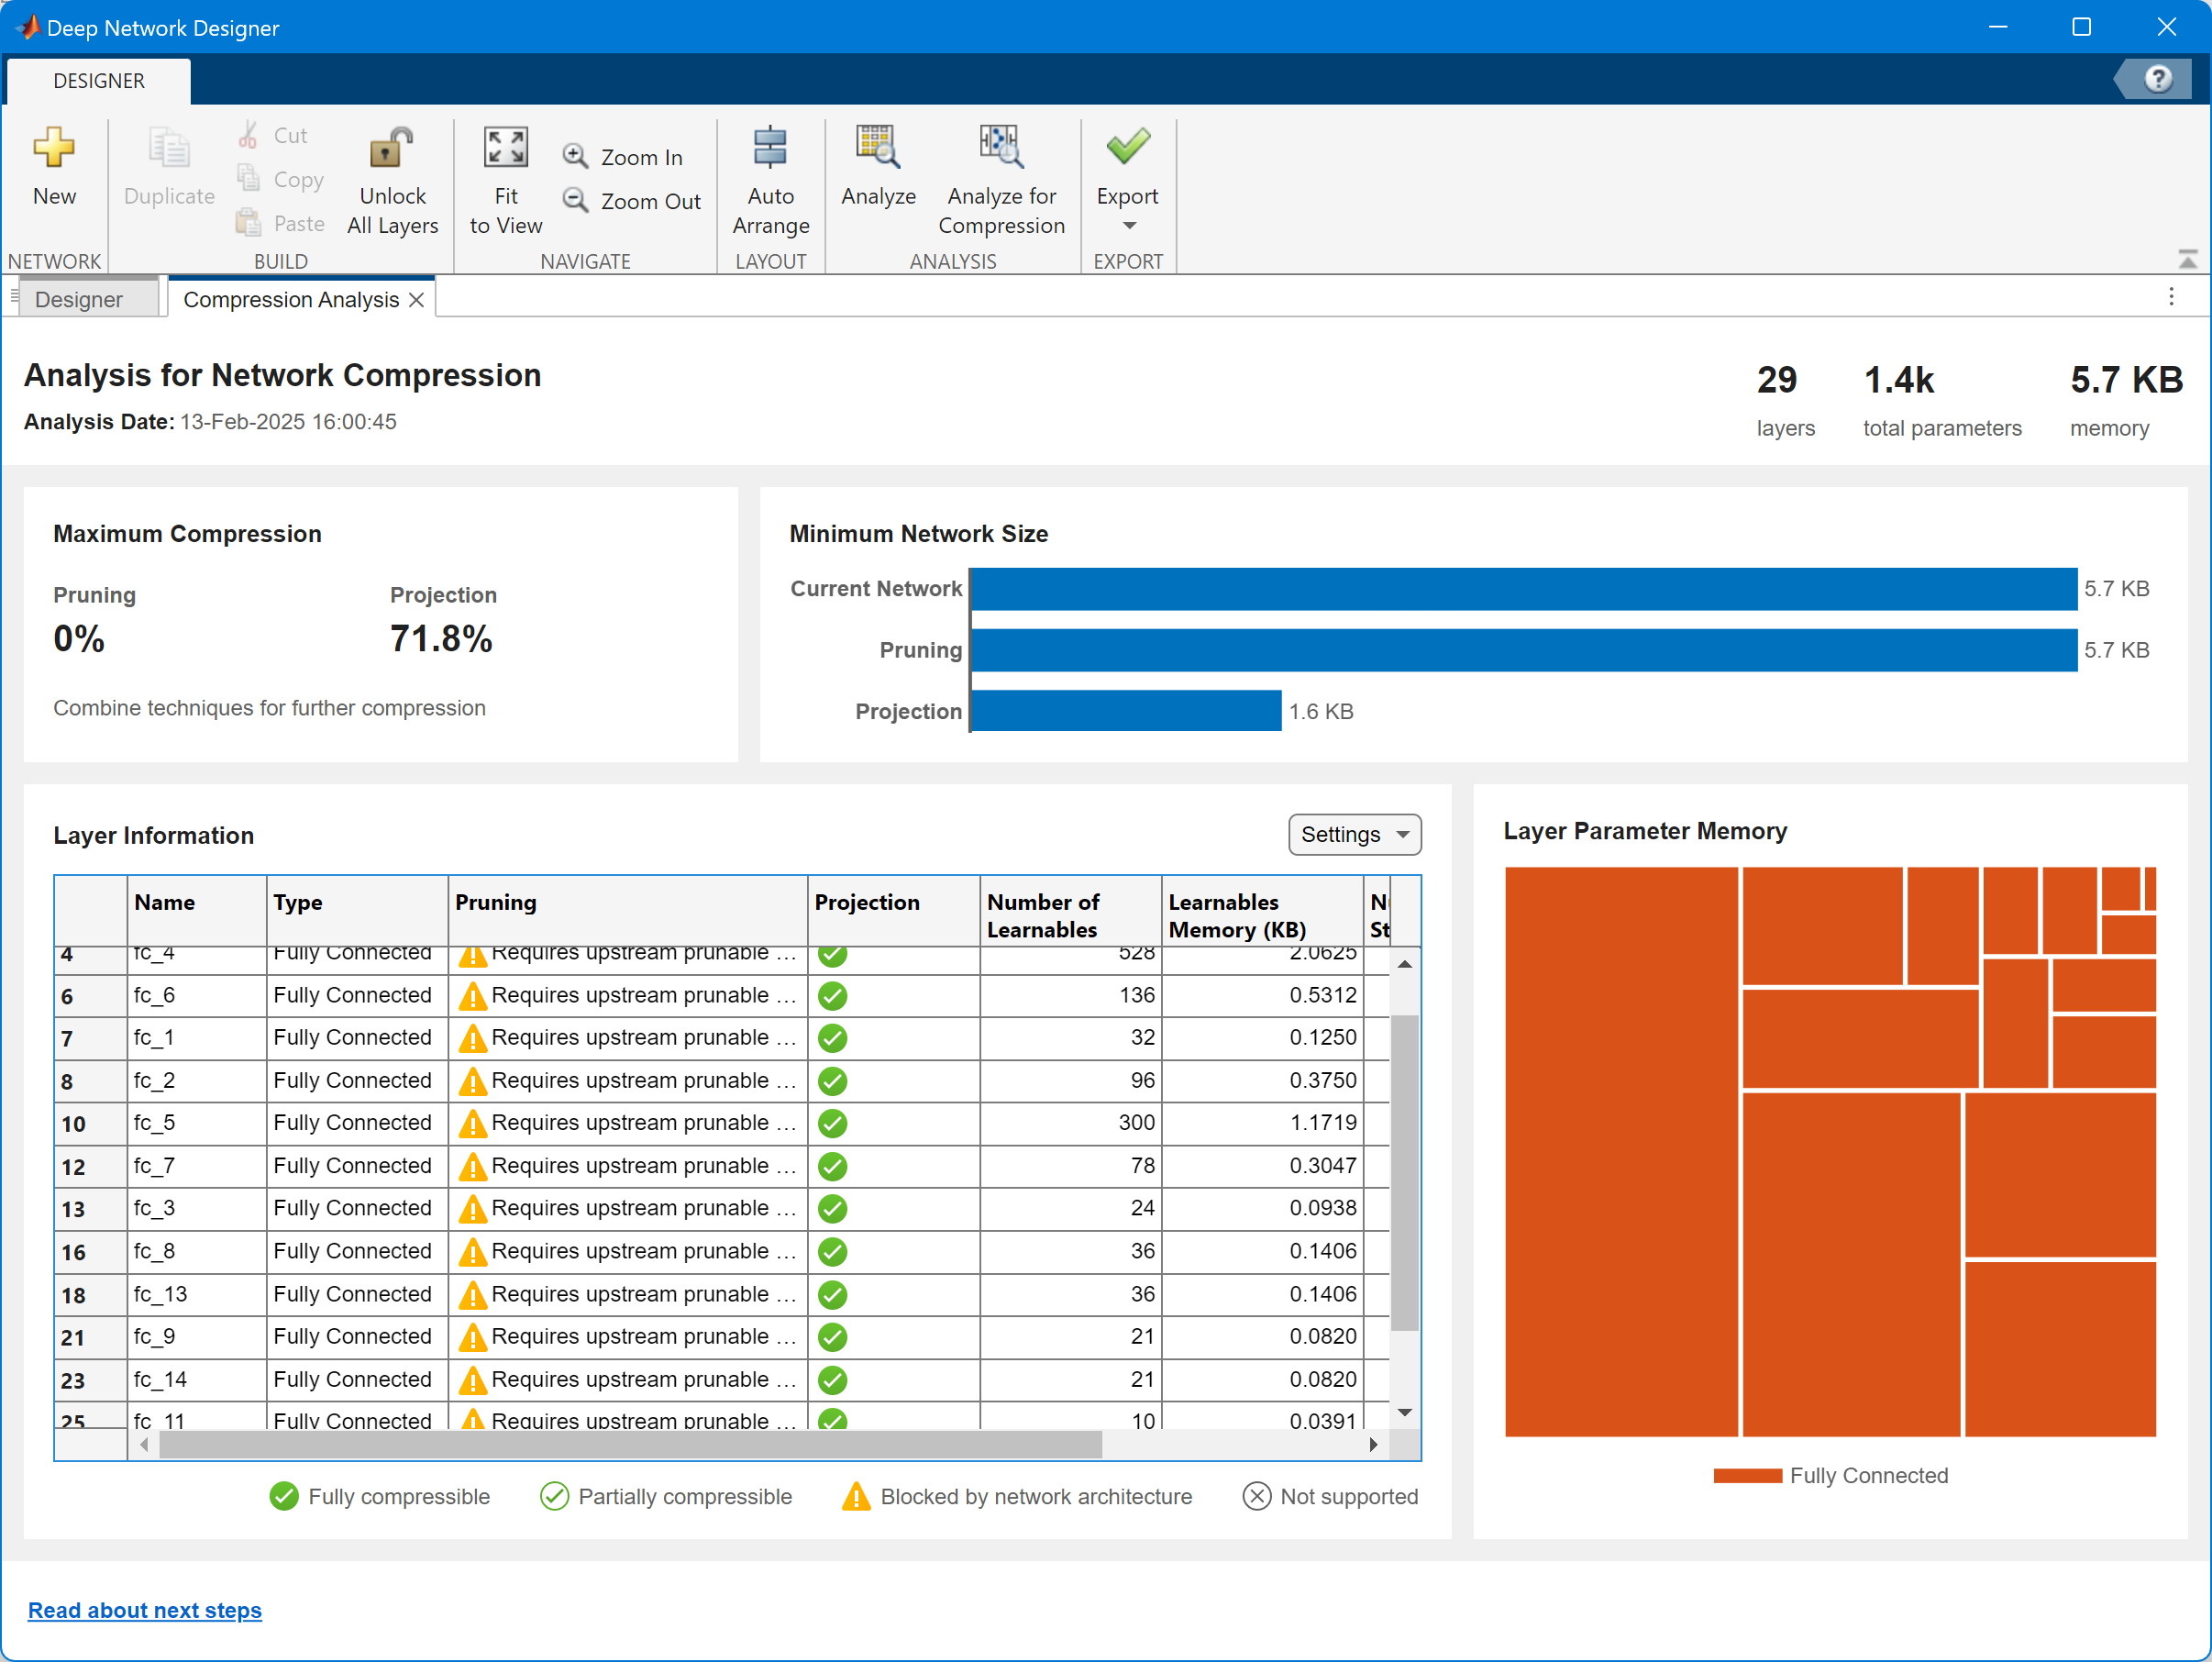

## Train the network with options

Specify the training options that are suitable for the problem. 

- Train the network using Adam.

- Train using mini-batches of size 64.

- Shuffle the data every epoch.

- Monitor the network accuracy during training by specifying validation data.

- Display the training progress in a plot and suppress the verbose command window output.

The software trains the network on the training data and calculates the accuracy on the validation data at regular intervals during training. The validation data is not used to update the network weights.

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingRMSE    ValidationRMSE
    _________    _____    ___________    _________    ____________    ______________    ____________    ______________
            0        0       00:00:11         0.05                            11.354                            3.3696
            1        1       00:00:12         0.05          8.4499                            2.9069                  
            5        1       00:00:25         0.05          7.8163             11.54          2.7958            3.3971
           10        1       00:00:29         0.05          8.1393            8.3505          2.8529            2.8897
           15        1       00:00:32         0.05            5.34            6.9623          2.3108            2.6386
           20        1       00:00:34         0.05           1.707             3.123          1.3065            1.7672
           25        1       00:00:37         0.

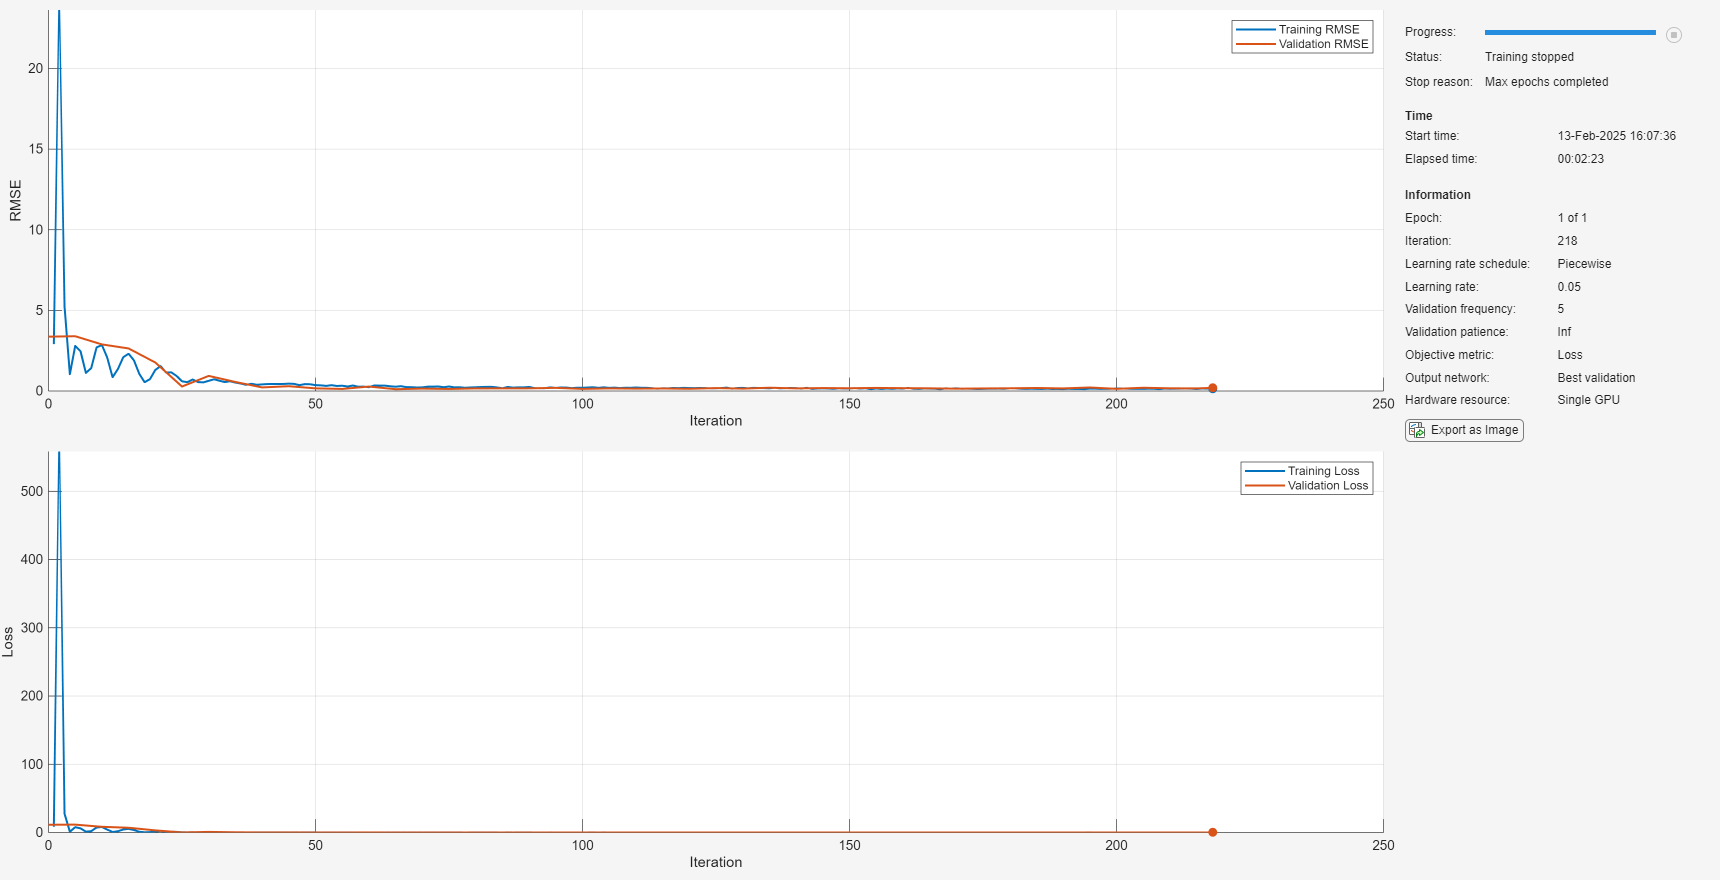

options = trainingOptions("adam", ...
    InitialLearnRate= 0.05 , ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.2, ...
    LearnRateDropPeriod=5, ...
    MaxEpochs=1, ...
    MiniBatchSize=64, ...
    ValidationData= Ds_Val, ...
    ValidationFrequency= 5, ...
    SequenceLength="shortest", ...
    Metrics="rmse",...
    Plots="training-progress");

tnet = trainnet(Ds_Train{1}, Ds_Train{2}, net, "mse", options);

Perform tests using the trained network and report Mean Squared Errors (MSE). 

ypred = predict(tnet,XTest);
% calculate MSE
squaredDifferences = (ypred - TTest).^2;
mse = mean(squaredDifferences)  % Percentage

mse = single
   0.0125336


% choose to save the trained network
save("netUsed.mat", "net", "tnet"); 

## Export the network to ONNX format

Import and export ONNX™ (Open Neural Network Exchange) models within MATLAB for interoperability with other deep learning frameworks. 

`Function exportONNXNetwork(`[`net`](https://www.mathworks.com/help/deeplearning/ref/exportonnxnetwork.html#mw_844c3879-ae5e-4704-8595-20250a86a2ef)`,`[`filename`](https://www.mathworks.com/help/deeplearning/ref/exportonnxnetwork.html#mw_247bf7b4-1227-4b76-93ea-604cc68161a9)`)` exports the deep learning network `net` with weights to the ONNX™ format file `filename`. If `filename` exists, then `exportONNXNetwork` overwrites the file.

filename = "TrainedFCNet.onnx";
exportONNXNetwork(tnet,filename); 